Main file

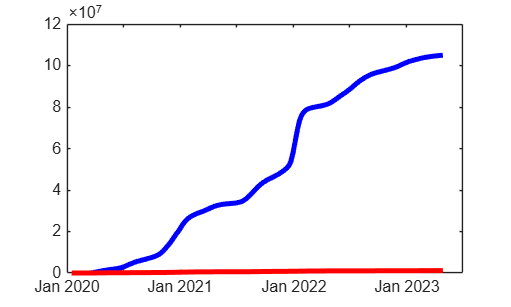

bad_tab_data = readtable("Weekly_United_States_COVID-19_Cases_and_Deaths_by_State_-_ARCHIVED_20261001.csv", "Delimiter", ",");
tab_data = sortrows(bad_tab_data, 1);

badWeekData = tab_data.start_date;
badInfectedData = tab_data.tot_cases;
badDeathsData = tab_data.tot_deaths;
badInfectedData2 = tab_data.new_cases;
badDeathsData2 = tab_data.new_deaths;
weekData = [];
weekData2 = [];
infectedData = [];
deathsData = [];
infectedData2 = [];
deathsData2 = [];


for i= 1 : 60: length(badWeekData) - 60
    weekData = [weekData, badWeekData(i)];
    infectedData = [infectedData, sum(badInfectedData(i:i+60))];
    deathsData = [deathsData, sum(badDeathsData(i:i+60))];
end

figure()
plot(weekData, infectedData, 'b', 'LineWidth', 3, 'DisplayName', 'Infected'); hold on
plot(weekData, deathsData, 'r', 'LineWidth', 3, 'DisplayName', 'Dead')
hold off;

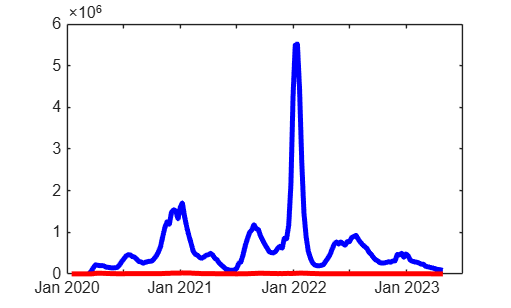


for i= 1 : 60: length(badWeekData) - 60
    weekData2 = [weekData2, badWeekData(i)];
    infectedData2 = [infectedData2, sum(badInfectedData2(i:i+60))];
    deathsData2 = [deathsData2, sum(badDeathsData2(i:i+60))];
end

figure()
plot(weekData2, infectedData2, 'b', 'LineWidth', 3, 'DisplayName', 'Infected'); hold on
plot(weekData2, deathsData2, 'r', 'LineWidth', 3, 'DisplayName', 'Dead')
hold off;